clear
close all
clc

load("Guitar03.mat")

figure(1)
ta = 1/fa;
t = (0:(length(x)-1))*ta;
subplot(1,2,1)
plot(t,x)
title('Sinal original')
xlabel('Tempo (seg)')
ylabel('Sinal')
% sound(x,fa)

MaxDelay = 0.3;
NumComp = 15;
Freq = 1;
Delay = 1;
Gain = 0.5; % 0 < Gain < 1
%y = Chorus(x,fa,MaxDelay,NumComp);
%y = Flanger(x,fa,MaxDelay,Freq)

y =    -0.0001
   -0.0001
   -0.0001
   -0.0002
   -0.0002
   -0.0001
   -0.0001
   -0.0001
   -0.0002
   -0.0003


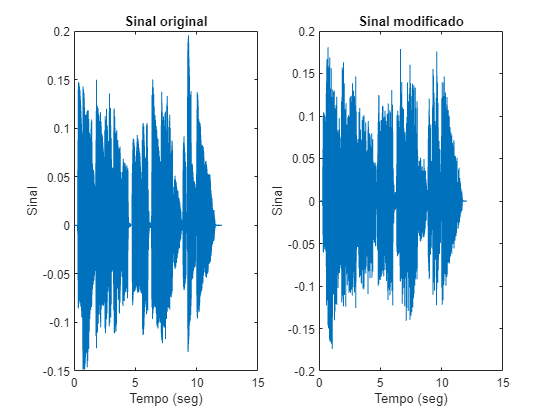

y = Reverb(x,fa,Delay,Gain);
subplot(1,2,2)
plot(t,y)
title('Sinal modificado')
xlabel('Tempo (seg)')
ylabel('Sinal')

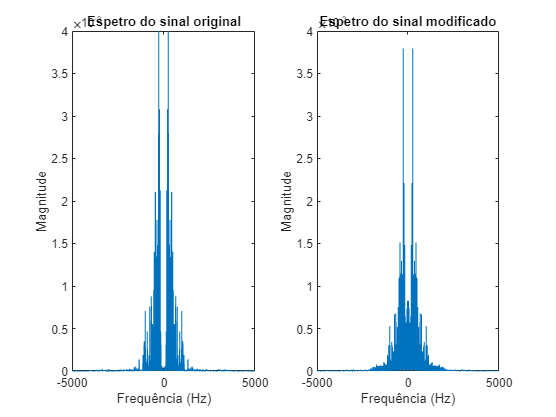

sound(y,fa)

figure(2)
subplot(1,2,1)
[X,fx] = AnotherEspetro(x,ta);
plot(fx,abs(X))
xlim([-5e3 5e3])
ylim([0 4e-3])
title('Espetro do sinal original')
xlabel('Frequência (Hz)')
ylabel('Magnitude')

subplot(1,2,2)
[Y,fy] = AnotherEspetro(y,ta);
plot(fy,abs(Y))
xlim([-5e3 5e3])
ylim([0 4e-3])
title('Espetro do sinal modificado')
xlabel('Frequência (Hz)')
ylabel('Magnitude')


% Para o ex. 4, trocar a Fa para metade.